# Attitude Controller Check

Jérémie Xavier Joseph Bannwarth, 28/03/2017

## Summary

Check how the attitude controller works.

## Controller inputs and constants

Inputs:

thrust_sp = 0.5;
q_sp  = EulerToQuat( deg2rad( [25, -10, 10] ) );
q_att = EulerToQuat( deg2rad( [0, 0, 0] ) );
R_sp  = QuatToRot( q_sp );
R     = QuatToRot( q_att );
roll_rate = 0;
pitch_rate = 0;
yaw_rate = 0;

Constants:

att_p = [6.5; 6.5; 2.8];
rates_p = [0.15; 0.15; 0.2];
rates_i = [0.05; 0.05; 0.1];
rates_d = [0.003; 0.003; 0];
rate_ff = [0; 0; 0];
dt = 0.002;

Initialize:

rates_int = 0;
rates_prev = 0;

## Find shortest path to target

The rotation matrices $\mathbf{R}_z$ and $\mathbf{R}_{\mathrm{sp}_z}$ are used to represent the current and desired orientation of the UAV respectively. Such matrices can be thought of as a reference frame defined by three orthogonal normalized vectors in $\mathcal{ℝ}^3$:$\mathbf{R}_x$, $\mathbf{R}_y$, and $\mathbf{R}_z$:


$$\mathbf{R} = \pmatrix{ \mathbf{R}_x & \mathbf{R}_y & \mathbf{R}_z } = 
\pmatrix{x_1 & y_1 & z_1 \cr
x_2 & y_2 & z_2 \cr
x_3 & y_3 & z_3}.$$


Using this representation, we can visualise the current and desired orientation graphically using the following code.

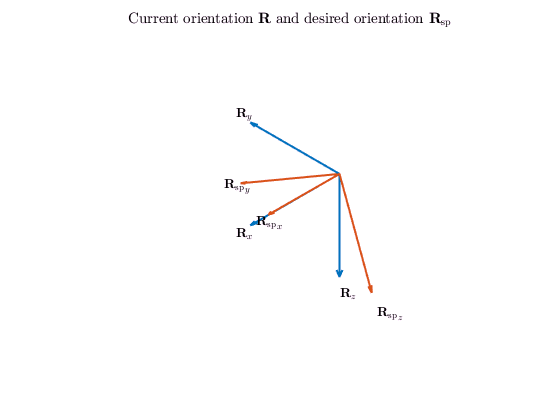

figure('Name', 'Rotation matrices');
axes( 'dataaspectratio', [1 1 1], 'projection', 'orthographic' )
title('Current orientation $\mathbf{R}$ and desired orientation $\mathbf{R}_\mathrm{sp}$', 'interpreter', 'latex')
cmap = get(gca,'colororder');
h(1:3) = PlotReferenceFrame( R,    1, '\mathbf{R}',      cmap(1,:) );
h(4:6) = PlotReferenceFrame( R_sp, 1, '\mathbf{R}_\mathrm{sp}', cmap(2,:) );
xlim auto; ylim auto; zlim auto
view([1 1 1])
% legend(h(3:4), {'cur' 'sp'});
set(findobj(gcf, 'type', 'axes'), 'Visible', 'off') % Clean up graph
set(findall(gca, 'type', 'text'), 'Visible', 'on');

The approach taken by the PX4 attitude controller's attitude loop is to separate the control action into two: first, roll/pitch and then yaw. Aligning $\mathbf{R}_z$ and $\mathbf{R}_{ \mathrm{sp}_z }$ can be done purely using roll and pitch, so it is done first. 

% Try to move thrust vector shortest way, because yaw response is slower than roll/pitch
R_z = R(:,3);
R_sp_z = R_sp(:,3);

Here we look at $\mathbf{R}_z$ and $\mathbf{R}_{ \mathrm{sp}_z }$ graphically.

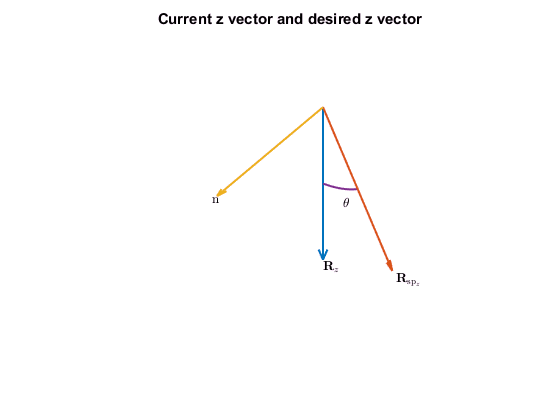

figure('Name', 'Z axes');
axes( 'dataaspectratio', [1 1 1], 'projection', 'orthographic' )
title('Current z vector and desired z vector')
cmap = get(gca,'colororder');
PlotVector( R_z, 1, '$\mathbf{R}_z$', cmap(1,:), '' )
PlotVector( R_sp_z, 1, '$\mathbf{R}_{\mathrm{sp}_z}$', cmap(2,:), '' )
PlotVector( cross(R_z, R_sp_z)./norm(cross(R_z, R_sp_z)), 1, 'n', cmap(3,:), '' )
PlotArc( R, R_sp_z, 0.5, '$\theta$', cmap(4,:) )
view([1 1 1])
set(findobj(gcf, 'type','axes'), 'Visible', 'off') % Clean up graph
set(findall(gca, 'type', 'text'), 'Visible', 'on');

We want to rotate from $\mathbf{R}_z$ to $\mathbf{R}_{ \mathrm{sp}_z }$ in the shortest path. The rotation required to simply align $\mathbf{R}_z$ and $\mathbf{R}_{ \mathrm{sp}_z }$ (without taking the UAV's yaw into consideration), can be represented as a rotation matrix $\mathbf{R}_\text{rp}$ (where $_\text{rp}$ stands for 'roll pitch'), or in axis angle form as the error $\theta$ around the unit-length vector $\mathbf{n}$ which is normal to $\mathbf{R}_z$ and $\mathbf{R}_{ \mathrm{sp}_z }$.

Since $|\mathbf{R}| = |\mathbf{R}_{\mathrm{sp}_z}| = 1$, we can use the properties of the cross and dot products to find $\theta$ and $\mathbf{n}$:


$$\mathbf{R}_z \times \mathbf{R}_{\mathrm{sp}_z} = |\mathbf{R}_z| |\mathbf{R}_{\mathrm{sp}_z}|\mathbf{n} \, {\sin\theta}
\rightarrow \sin\theta = \left|\mathbf{R}_z \times \mathbf{R}_{\mathrm{sp}_z}\right|, \; \mathbf{n} = \mathbf{R}^\top \frac{1}{\sin\theta} \left( \mathbf{R}_z \times \mathbf{R}_{\mathrm{sp}_z} \right)$$



$$\mathbf{R} \cdot \mathbf{R}_{\mathrm{sp}_z} = |\mathbf{R}|\cos\theta \rightarrow
\cos\theta = \mathbf{R} \cdot \mathbf{R}_{\mathrm{sp}_z}$$



$$\theta = \arctan\left( \frac{ | \mathbf{R}_z \times \mathbf{R}_{\mathrm{sp}_z} | }{  \mathbf{R}_z \cdot \mathbf{R}_{\mathrm{sp}_z} \right)$$


$\theta$ and $\mathbf{n}$ can be combined as a single vector $\mathbf{e}_R$:


$$\mathbf{e}_R = \theta \mathbf{n}.$$


The PX4 implementation is as follow:

% Axis and sin(angle) of desired rotation
e_R = R' * cross(R_z, R_sp_z);             % sin theta * n

% Calculate angle error
e_R_z_sin = norm(e_R);                     % sin theta
e_R_z_cos = dot(R_z, R_sp_z);              % cos theta

% Calculate rotation matrix after roll/pitch only rotation
if ( e_R_z_sin > 0.0 )
    e_R_z_angle = atan2(e_R_z_sin, e_R_z_cos); % theta
    e_R_z_axis = e_R ./ e_R_z_sin;             % n
    
    e_R = e_R_z_axis .* e_R_z_angle;           % e_R

The cross product between two vectors $\mathbf{a}$ and $\mathbf{b}$ can also be expressed as a matrix multiplication:


$$\mathbf{a} \times \mathbf{b} = \mathbf{A} \mathbf{b}, \; \mathrm{where} \; \mathbf{A} =
\pmatrix{0 & -a_3 & a_2 \cr
a_3 & 0 & -a_1 \cr
-a_2 & a_1 & 0}.$$


A rotation matrix representing the rotation $\mathbf{e}_R$ can be obtained by the following equation:


$$\mathbf{R}_\text{rp} = \mathbf{R} \left(
\mathbf{I}
+
\mathbf{E}_R \sin\theta
+
{\mathbf{E}_R}^2 \left( 1 - \cos\theta \right)
\right)$$


where $\mathbf{E}_R$ is the cross-product matrix form of $\mathbf{e}_R$. Full derivation for this equation can be found at:

S. van Der Walt, *The 3 x 3 rotation matrix. *Available: [http://dip.sun.ac.za/~stefan/TWB264/notas/engels/12_rot_3x3_eng.pdf](http://dip.sun.ac.za/~stefan/TWB264/notas/engels/12_rot_3x3_eng.pdf).

These equations are implemented in the PX4 firmware as follow:

    % Cross product matrix for e_R_axis
    e_R_cp = zeros(3,3); % E_R
    e_R_cp(1, 2) = -e_R_z_axis(3);
    e_R_cp(1, 3) =  e_R_z_axis(2);
    e_R_cp(2, 1) =  e_R_z_axis(3);
    e_R_cp(2, 3) = -e_R_z_axis(1);
    e_R_cp(3, 1) = -e_R_z_axis(2);
    e_R_cp(3, 2) =  e_R_z_axis(1);
    
    % Rotation matrix for roll/pitch only rotation
    R_rp = R * ( eye(3,3) + e_R_cp * e_R_z_sin + e_R_cp * e_R_cp * (1.0 - e_R_z_cos) );
else
    % Zero roll/pitch rotation
    R_rp = R;
end

We now have a temporary 'error' vector, $\mathbf{e}_R$, which is still missing its yaw elements:

e_R

e_R =     0.4601
   -0.0847
         0


## Yaw Control

The $z$ axes of the $\mathbf{R}_\mathrm{rp}$ and $\mathbf{R}_\mathrm{sp}$ matrices are identical:

disp(R_rp(:,3))

   -0.0816
   -0.4435
    0.8925



disp(R_sp(:,3)) 

   -0.0816
   -0.4435
    0.8925



The attitude controller applies a weight on the yaw control which is defined as


$$w_\psi = {R_{\mathrm{sp}_{3,3}}}^2$$


% Calculate weight for yaw control
yaw_w = R_sp(3, 3) * R_sp(3, 3); % w_psi

Now, we calculate the yaw error:


$$e_{R_z} =
\arctan
\left(
\frac{ \left( \mathbf{R}_{\mathrm{rp}_x} \times \mathbf{R}_{\mathrm{sp}_x} \right)
\cdot \mathbf{R}_{\mathrm{sp}_z}
}{ 
\mathbf{R}_{\mathrm{rp}_x} \cdot \mathbf{R}_{\mathrm{sp}_x} } \right) w_\psi$$


Since the $z$-axes of  $\mathbf{R}_\mathrm{rp}$ and $\mathbf{R}_\mathrm{sp}$ are aligned, $\mathbf{R}_{\mathrm{rp}_x} \times \mathbf{R}_{\mathrm{sp}_x}$ and  $\mathbf{R}_{\mathrm{sp}_z}$ are coincident. Therefore,  $\left( \mathbf{R}_{\mathrm{rp}_x} \times \mathbf{R}_{\mathrm{sp}_x} \right) \cdot \mathbf{R}_{\mathrm{sp}_z} = | \mathbf{R}_{\mathrm{rp}_x} \times \mathbf{R}_{\mathrm{sp}_x} |$ if $| \mathbf{R}_{\mathrm{rp}_x} \times \mathbf{R}_{\mathrm{sp}_x} | \leq |\mathbf{R}_{\mathrm{sp}_z}|$, which is true in all cases since $| \mathbf{R}_{\mathrm{rp}_x} \times \mathbf{R}_{\mathrm{sp}_x} | = | \mathbf{R}_{\mathrm{rp}_x} | | \mathbf{R}_{\mathrm{sp}_x} | \sin \psi$, where $|\mathbf{R}_{\mathrm{rp}_x}| = |\mathbf{R}_{\mathrm{sp}_x}| = 1$, and $\max( \sin \psi) = 1$ . This means that 


$$e_{R_z} =
\arctan
\left(
\frac{ | \mathbf{R}_{\mathrm{rp}_x} \times \mathbf{R}_{\mathrm{sp}_x} |
}{ 
\mathbf{R}_{\mathrm{rp}_x} \cdot \mathbf{R}_{\mathrm{sp}_x} } \right) w_\psi = \psi w_\psi$$


where $\psi$ is the yaw error.

% R_rp and R_sp has the same Z axis, calculate yaw error
R_sp_x = R_sp(:, 1);
R_rp_x = R_rp(:, 1);
e_R(3) = atan2( dot( cross(R_rp_x, R_sp_x), R_sp_z), dot(R_rp_x, R_sp_x) ) * yaw_w;

This is a bit hard to decipher, so let's plot it step-by-step:

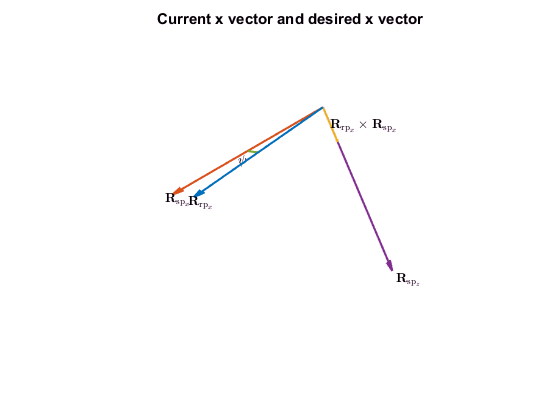

figure('Name', 'Yaw control');
axes( 'dataaspectratio', [1 1 1], 'projection', 'orthographic' )
title('Current x vector and desired x vector')
cmap = get(gca,'colororder');
PlotVector( R_rp_x, 1, '$\mathbf{R}_{\mathrm{rp}_x}$', cmap(1,:), '' )
PlotVector( R_sp_x, 1, '$\mathbf{R}_{\mathrm{sp}_x}$', cmap(2,:), '' )
PlotVector( R_sp_z, 1, '$\mathbf{R}_{\mathrm{sp}_z}$', cmap(4,:), '' )
PlotVector( cross(R_rp_x, R_sp_x), 1, '$\mathbf{R}_{\mathrm{rp}_x} \times \mathbf{R}_{\mathrm{sp}_x}$', cmap(3,:), 'side' )
PlotArc( R_sp, R_rp_x, 0.5, '$\psi$', cmap(5,:), 1 )
view([1 1 1])
set(findobj(gcf, 'type','axes'), 'Visible', 'off') % Clean up graph
set(findall(gca, 'type', 'text'), 'Visible', 'on');

The attitude controller has a special way to handle large rotations:

if ( e_R_z_cos < 0.0 )
    % For large thrust vector rotations use another rotation method:
    % calculate angle and axis for R -> R_sp rotation directly
    q_error = RotToQuat( R' * R_sp );
    
    if ( q_error(1) >= 0.0 )
        e_R_d =  q_error(2:end) * 2.0; % Still not 100% sure
    else
        e_R_d = -q_error(2:end) * 2.0;
    end
    
    
    % Use fusion of Z axis based rotation and direct rotation
    direct_w = e_R_z_cos * e_R_z_cos * yaw_w;
    e_R = e_R * (1.0 - direct_w) + e_R_d * direct_w;
end

We now have the final 'error' vector, $\mathbf{e}_R$:

e_R

e_R =     0.4601
   -0.0847
    0.1699


## Attitude control law

Finally, a simple proportional control law is applied to reduce the error to 0:


$$\dot{\phi}_\mathrm{sp} = P_\phi e_{R_x}$$



$$\dot{\theta}_\mathrm{sp} = P_\theta e_{R_y}$$



$$\dot{\psi}_\mathrm{sp} = P_\psi e_{R_z}$$


% Calculate angular rates setpoint
rates_sp = att_p .* e_R;

The controller applies some saturation to the rates, which do not usually come in the way.

% Limit rates
% for i = 1:3
%     if ( (self.v_control_mode.flag_control_velocity_enabled || self.v_control_mode.flag_control_auto_enabled) && ...
%          ~self.v_control_mode.flag_control_manual_enabled)
%         self.rates_sp(i) = constrain(self.rates_sp(i), -self.params.auto_rate_max(i), self.params.auto_rate_max(i));
%     else
%         self.rates_sp(i) = constrain(self.rates_sp(i), -self.params.mc_rate_max(i), self.params.mc_rate_max(i));
%     end
% end

We thus have the final desired rates:

rad2deg(rates_sp)

ans =   171.3626
  -31.5276
   27.2625


## Attitude rates

The cade for calculating the attitude rates has a few saturations and optional features which are not included in this section, as they do not have a significant effect on the output.

First, we compute the rate error. We define the rate vector as $\nu = \pmatrix{ \dot{\phi} & \dot{\theta} & \dot{\psi} }^\top$. Therefore, the rate error $\mathbf{e}_\nu$ is defined as


$$\mathbf{e}_\nu = \nu_\mathrm{sp} - \nu.$$


This is implemented in the PX4 controller in a simple fashion.

% Current body angular rates
rates = [roll_rate; pitch_rate; yaw_rate];

% Angular rates error
rates_err = rates_sp - rates;

rates_err =     2.9908
   -0.5503
    0.4758


The output of the rate controller is a vector of normalised roll, pitch, and yaw commands, $c$. The rate controller is a simple discrete-time PID controller. The code supports feedforward inputs, however the term is set to 0 by default. Assuming no integral saturation occurs,


$$c_T = P_\nu \circ \mathbf{e}_{\nu_T} + D_\nu \circ \frac{1}{\Delta T} \left( \nu_{T-1} - \nu_T \right) + \sum^{T}_{t=0} I_\nu \mathbf{e}_{\nu_t} \Delta T.$$


% Perform the integration using a first order method and do not propaate the result if out of range or invalid
rates_int = rates_int + rates_i .* rates_err * dt;

att_control = rates_p .* rates_err + rates_int + rates_d .* (rates_prev - rates) ./ dt + rate_ff .* rates_sp;

rates_sp_prev = rates_sp;
rates_prev = rates;

We thus have the final controller output:

att_control

att_control =     0.4489
   -0.0826
    0.0953
